
clear; clc;

## Generate data


x = [[0.01:0.01:1];[0.01:0.01:1]]';
rng(0,'twister');  % 产生可预测的随机数
y = (x(:,1).^2+x(:,2).^2)/2 ;




## Train NN

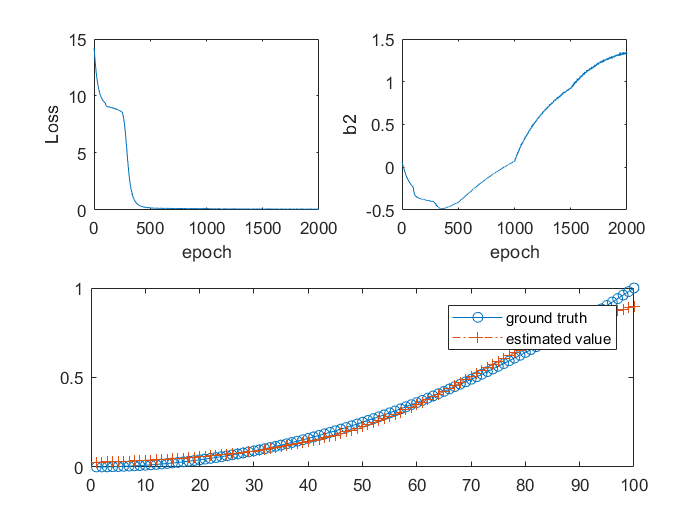

% Dims of input layer, hidden layer, and output layer
d0 = 2; d1 = 20; d2 = 1;

%  Init W1,W2,b1,b2
W1 = 0.1*randn(d1,d0);
b1 = 0.1*randn(d1,1);
W2 = 0.1*randn(d2,d1);
b2 = 0.1*randn(d2,1);


for ii = 1 : 2000  % 2000 epoch
    % SGD
    P = randperm(100);
    X = x(P,:);
    Y = y(P);
    
    %% Learning rate from 5 to 0.001 during training
    if ii > 1500
        alpha = 5;
    elseif ii > 1000
        alpha = 0.5;
    elseif ii > 500
        alpha = 0.1;
    elseif ii > 250
        alpha = 0.05;
    elseif ii > 100
        alpha = 0.01;
    else
        alpha = 0.001;
    end
    
    for i = 1 : 100 
        Z1 = W1 * X(i,:)'+b1;
        h = mysigmoid(Z1);
        Z2 = W2 * h + b2;
        y_out = mysigmoid(Z2);
        loss(i) = norm(Y(i)-y_out)^2;
        % Compute Gradient
        [delta2_W2,delta2_b2,delta1_W1,delta1_b1] = my_grad(X(i,:)',y_out,Y(i),Z1,Z2,W2,d0,d1,d2);
        
        % updating
        W1 = W1 - alpha* delta1_W1;
        b1 = b1 - alpha* delta1_b1';
        W2 = W2 - alpha* delta2_W2;
        b2 = b2 - alpha* delta2_b2;
    end

    b(ii) = b2;
    % Loss
    loss_epoch(ii) =  sum(loss);
end

%% Test
for i = 1 : 100
    Z1 = W1 * x(i,:)'+b1;
    h = mysigmoid(Z1);
    Z2 = W2 * h + b2;
    y_out(i) = mysigmoid(Z2); 
end

subplot(2,2,1)
plot(loss_epoch)
ylabel('Loss')
xlabel('epoch')
subplot(2,2,2)
plot(b)
xlabel('epoch')
ylabel('b2')
subplot(2,1,2)
plot(y,'o-')
hold on
plot(y_out,'+-.')
legend('ground truth','estimated value')